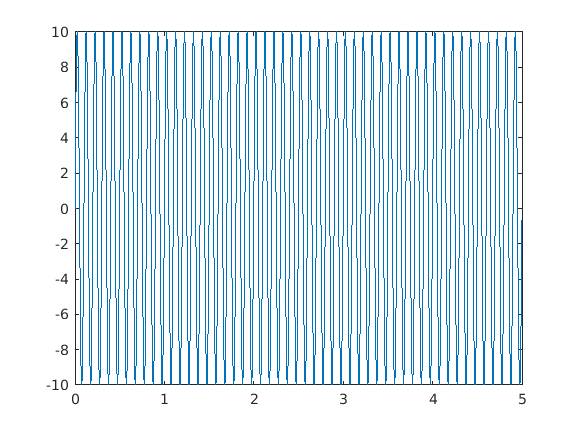

fs1=1000; 
N1=5000;
A1=10;
ph1=0;
fc1=10;
dt1=1/fs1;
t1=(0:N1-1)*dt1;
S1=A1*sin(2*pi*fc1*t1+ph1);
plot(t1(1:N1),S1(1:N1));

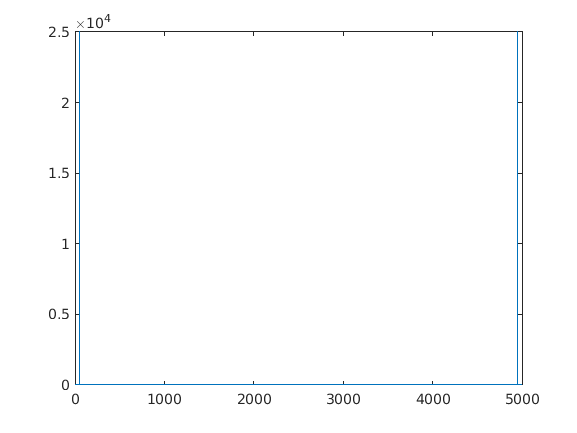

y1=abs(fft(S1));
plot(y1);

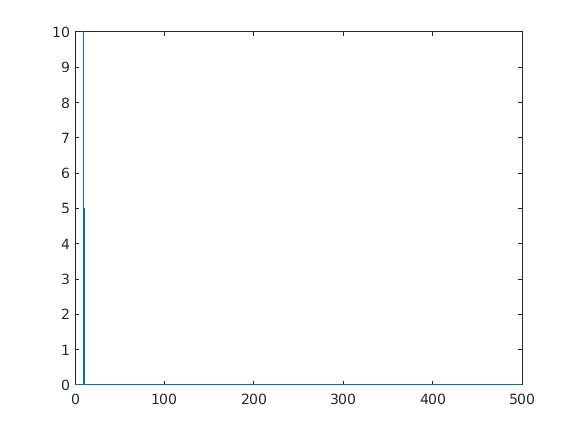

P2=y1/N1;
P1=P2(1:N1/2+1);
P1(2:end-1)=2*P1(2:end-1);
f1=fs1*(0:(N1/2))/N1;
plot(f1,P1);

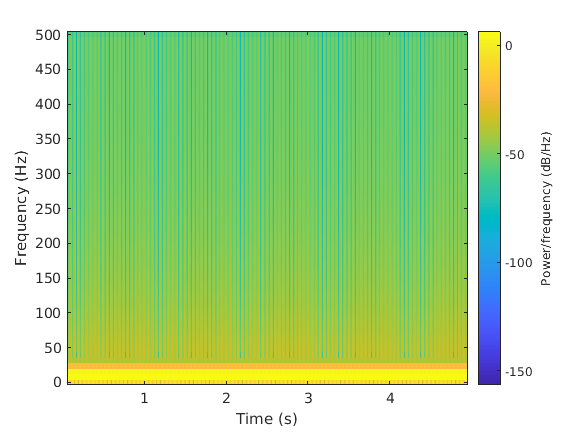

spectrogram(S1,128,120,128,1e3,'yaxis');

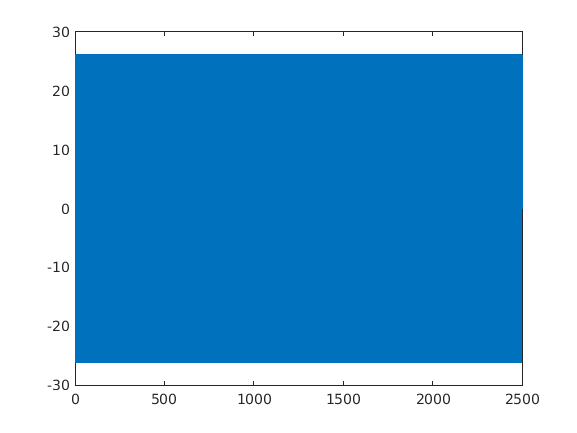


fs2=2000;
N2=2500;
A2=100;
ph2=50;
fc2=1000;
dt2=1/fs2;
t2=(0:N2-1)*dt2;
S2=A2*sin(2*pi*fc2*t2+ph2);
plot(S2);

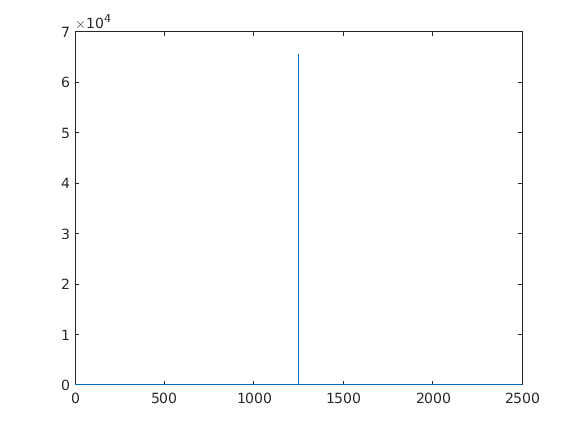

y2=abs(fft(S2));
plot(y2);

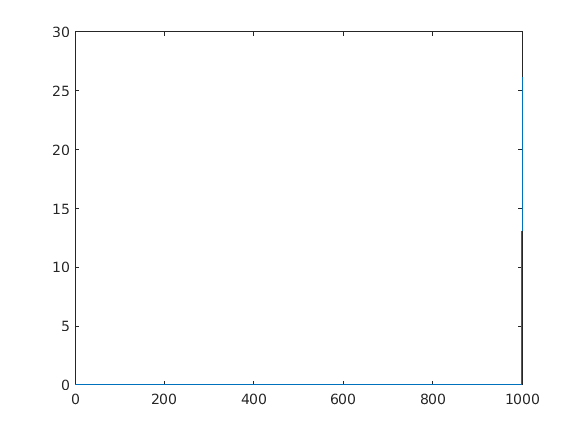

P4=y2/N2;
P3=P4(1:N2/2+1);
P3(2:end-1)=2*P3(2:end-1);
f2=fs2*(0:(N2/2))/N2;
plot(f2,P3);

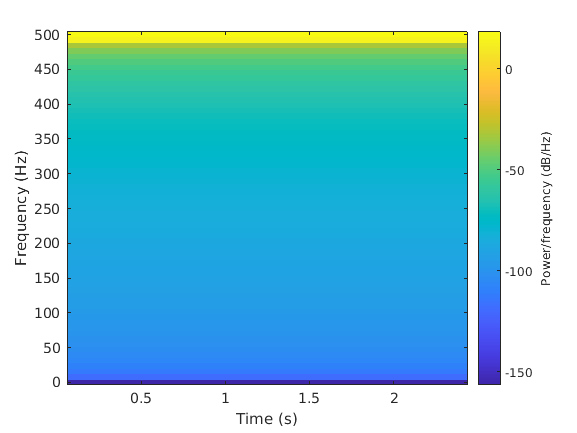


spectrogram(S2,128,120,128,1e3,'yaxis');